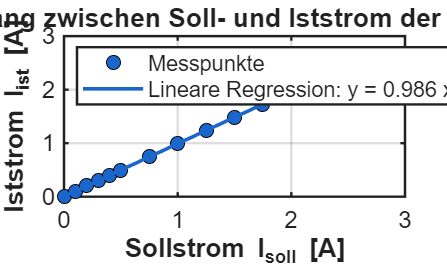

%% Messdaten: CAN-Stromregelung
% Marian – August 2026

% CAN-Werte (Hex) – optional, falls du sie später brauchst
can_hex = ["00","0A","14","1E","28","32","4B","64","7D","96","AF","C8","FA","FF"];

% Soll- und Ist-Stromwerte in Ampere
I_soll = [0, 0.1, 0.2, 0.3, 0.4, 0.5, 0.75, 1.0, 1.25, 1.5, 1.75, 2.0, 2.5, 2.55];
I_ist  = [0, 0.102, 0.202, 0.3, 0.401, 0.499, 0.745, 0.99, 1.238, 1.483, 1.73, 1.975, 2.469, 2.519];

%% Professioneller Plot: I_soll vs. I_ist
figure('Color','w'); % weißer Hintergrund für Publikationsqualität
hold on; grid on; box on;

% Datenpunkte
plot(I_soll, I_ist, 'o', ...
    'MarkerSize', 7, ...
    'MarkerFaceColor', [0.1 0.4 0.8], ...
    'MarkerEdgeColor', 'k');

% Lineare Regression (optional, aber sehr aussagekräftig)
p = polyfit(I_soll, I_ist, 1);
I_fit = polyval(p, I_soll);

plot(I_soll, I_fit, '-', ...
    'LineWidth', 1.8, ...
    'Color', [0.1 0.4 0.8]);

%% Achsen & Titel
xlabel('Sollstrom I_{soll} [A]', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Iststrom I_{ist} [A]', 'FontSize', 12, 'FontWeight', 'bold');
title('Zusammenhang zwischen Soll- und Iststrom der Stromregelung', ...
    'FontSize', 14, 'FontWeight', 'bold');

%% Legende
legend({'Messpunkte', sprintf('Lineare Regression: y = %.3f x + %.3f', p(1), p(2))}, ...
    'Location', 'northwest');

%% Achsenformatierung
set(gca, 'FontSize', 12, 'LineWidth', 1.2);